**HW 2**

**1) Which is more probable when rolling 2 six-sided dice: rolling snake eyes (two ones) or rolling sevens (dice sum to seven)? What is the ratio of probabilities?**

Rolling sevens is more likely. In order to roll snake eyes, one must roll a combination of 1 and 1, each of which is a probability of 1/6, so the total is 1/36. 

In order to roll sevens, there are multiple combinations: 1 and 6, 2 and 5, 3 and 4, and their opposites (6&1,etc). Since there are six combinations, each of which has a probability of 1/6, the total probability will be 6* (1/6 * 1/6) or 1/6, which is greater than 1/36.

**2) Following what we did in class, show how to use the convolution operator to determine the probability of the sum of 2 six sided dice. Do both analytically and numerically. Beware the implicit definition of the values (x-axis on histogram).**

Possible combinations of two six-sided dice range from 2 to 12. Every value inbetween (non-integers) and outside (below and above) is zero.

I will use a typing shortcut of "and opp" to mean 'and opposites' — to 1&3, the opposite is 3&1. For a combination where both results are the same (4&4), there is no opposite.

Similarly to math in part 1, probability for 2 is 1/36. 

Probability for the sum to be 3 is combinations 1&2 and opp, each of probability 1/36, so the total is 1/18.

Probability for the sum to be 4 is combinations 1&3, 2&2 and opp, each 1/36, so the total is 1/36 * 3 = 1/12.

I don't want to calculate the rest up to sum of 7, since the pattern is (sum total / 36). So 5 is 5/36, 6 is 1/6, 7 is 7/36.

After 7, the probabilities step down to 1/36 at sum of 12. So 8 is 1/6, 9 is 5/36, 10 is 1/12, 11 is 1/18, 12 is 1/36.

Next, I will do the same calculations using matlab.

First, I need to create the input vectors.

v1 = [0,1/6,1/6,1/6,1/6,1/6,1/6];
v2 = [0,1/6,1/6,1/6,1/6,1/6,1/6];

Use conv on the vectors to find the convolution of them.

conv1 = conv(v1,v2)

conv1 =          0         0    0.0278    0.0556    0.0833    0.1111    0.1389    0.1667    0.1389    0.1111    0.0833    0.0556    0.0278


Create an x-vector associated with the convolution results.

xVector = 0:12;

Plot the result.

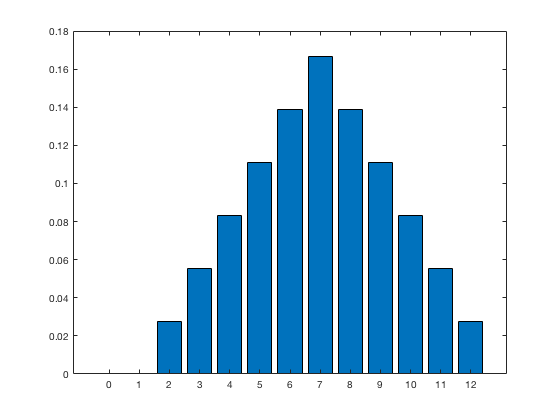

bar(xVector,conv1);

**3) Calculate the mean and the variance of the distribution in problem 2.**

The mean will be given by the sum of (vector of positions * vector of weights) divided by the sum of the vector of weights.

I expect a mean of 7, and I'm not sure about the variance, but it may be not an integer.

mean1 = ceil(sum(xVector .* conv1)/(sum(conv1))) %ceil to get rid of rounding since we know the answer is 7 exactly

mean1 = 7

The variance is given by the sum of ((position - mean)^2 * probability at position) for all positions.

varTerm = zeros(1,13);
for i = 1:13
    varTerm(i) = (xVector(i)-mean1)^2 * conv1(i);
end
var1 = sum(varTerm)

var1 = 5.8333

The variance kind of makes sense — that is about the answer I would expect.

**4) Repeat 2, graph the average of 10 dice. Is this a Gaussian distribution? Explain in depth.**

I will refrain from doing this analytically (as it is a disgusting amount of work), but I will do it using the properties of convolution functions. In order to get a convolution of 3 die rolls, I would take the convolution of the result of 2 die rolls with another die roll.

conv2 = conv(conv1,v1)

conv2 =          0         0         0    0.0046    0.0139    0.0278    0.0463    0.0694    0.0972    0.1157    0.1250    0.1250    0.1157    0.0972    0.0694    0.0463    0.0278    0.0139    0.0046


Test that the convolution works.

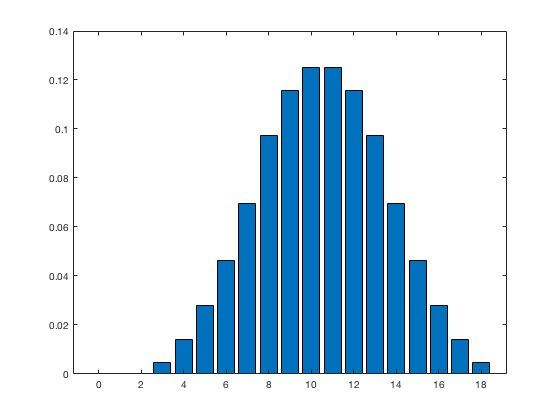

xVectorTrial = 0:18;
bar(xVectorTrial,conv2);

It works! Time to do this 10 times in a row without giving it any thought.

conv10 = conv(conv(conv(conv(conv(conv(conv(conv(conv2,v1),v1),v1),v1),v1),v1),v1),v1)

conv10 =          0         0         0         0         0         0         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0005    0.0009    0.0015    0.0026    0.0041    0.0063    0.0092    0.0130    0.0178    0.0235    0.0300    0.0370    0.0443    0.0514    0.0579    0.0633    0.0672    0.0692    0.0692    0.0672    0.0633    0.0579    0.0514    0.0443    0.0370    0.0300    0.0235    0.0178    0.0130


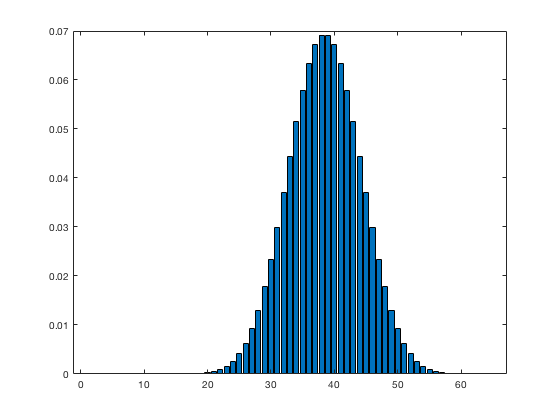

xVectorFinal = 0:66;
bar(xVectorFinal,conv10)

Although I wouldn't say this is exactly a Gaussian distribution yet, it is well on the way onto approaching a Gaussian distribution. It is centered about a mean value with something that could be defined as a sigma — but this distribution is discrete, and thus is not a true Gaussian. The way I view it is this distribution can be worked with in ways that many Gaussian distributions are treated (as long as one is careful about the discrete interpretations of probabilities and sigmas), but it is not truly a Gaussian.

**5) Show that the sum and average of an initially Gaussian distribution is also a Gaussian. How does the standard deviation of the resulting sum or average Gaussian change? Explore what this means for integrating a signal over time.**

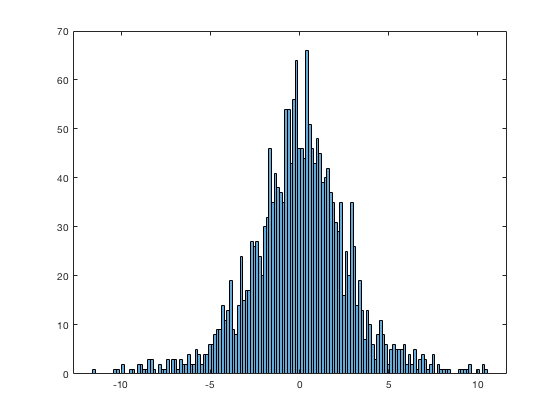

gaus1 = normrnd(0,1.6,1000,1);
gaus2 = normrnd(0,3.56,1000,1);
combination = [gaus1;gaus2];
histogram(combination,150);

It can be seen that the sum of the two Gaussians is also indeed a Gaussian. The distributions are not perfect as they are made from two sets of randomly distributed variables that follow a Gaussian distribution.

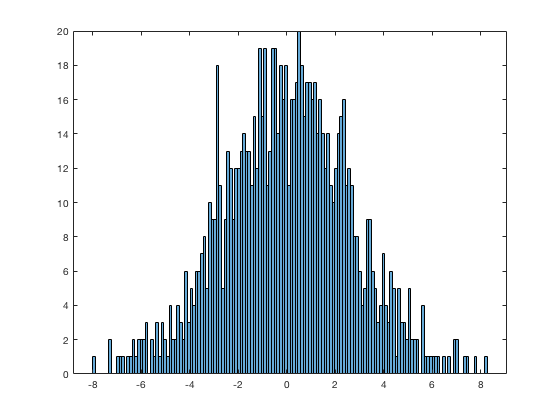

avgGauss = zeros(1,1000);
gaus1 = sort(gaus1);
gaus2 = sort(gaus2);
for i = 1:1000
    avgGauss(i) = (gaus1(i)+gaus2(i))/2;
end
histogram(avgGauss,150);

It can also be seen that the average of the two Gaussians is also a Gaussian.

std1 = std(gaus1)

std1 = 1.6667

std2 = std(gaus2)

std2 = 3.5759

std3 = std(combination)

std3 = 2.7902

std4 = std(avgGauss)

std4 = 2.6203

(std1 + std2)/2

ans = 2.6213

It seems like the standard deviation of the average of the distributions is close to the average of the individual standard deviations summed together. I am not sure I see a pattern for the simple sum of the stdev of Gaussians.

If integrating a signal over time, we expect the standard deviation to improve with how long the time has elapsed for — the longer an experiment is run, the more stdev will be averaged, thus leading to a higher confidence in the results.